# Pre-Emphasis Filter Using Deep Learning

pathToRecordingsFolder = fullfile(tempdir,'free-spoken-digit-dataset','recordings');
ads = audioDatastore(pathToRecordingsFolder);

lbls = filenames2labels(ads,ExtractBefore="_");
ads.Labels = lbls;
countlabels(lbls)

ans = 10×3 table
    Label    Count    Percent
    _____    _____    _______

      0       300       10   
      1       300       10   
      2       300       10   
      3       300       10   
      4       300       10   
      5       300       10   
      6       300       10   
      7       300       10   
      8       300       10   
      9       300       10   


rng default;
ads = shuffle(ads);
[adsTrain,adsTest] = splitEachLabel(ads,0.8,0.2);

transTrain = transform(adsTrain,@(x,info)helperReadData(x,info),'IncludeInfo',true);
transTest = transform(adsTest,@(x,info)helperReadData(x,info),'IncludeInfo',true);

## DCNN: 

numF = 12;
dropoutProb = 0.2;
layers = [
    sequenceInputLayer(1,'Name','input','MinLength',8192,...
         'Normalization',"none")

    convolution1dLayer(5,1,"name","pre-emphasis-filter",...
    "WeightsInitializer",@(sz)kronDelta(sz),"BiasLearnRateFactor",0)  

    stftLayer('Window',hamming(1280),'OverlapLength',900,...
    'Name','STFT') 
    
    convolution2dLayer(5,numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')
   
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    dropoutLayer(dropoutProb)
    globalAveragePooling2dLayer
    fullyConnectedLayer(numel(categories(ads.Labels)))
    softmaxLayer    
    ];
dlnet = dlnetwork(layers);

## Network Training

NumEpochs = 70;
miniBatchSize = 128;
learnRate = 0.001;

mbqTrain = minibatchqueue(transTrain,2,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat', {'CBT','CB'}, ... 
    'MiniBatchFcn', @processSpeechMB);

progress = "final-loss";
if progress == "training-progress"
    figure
    lineLossTrain = animatedline;
    ylim([0 inf])
    xlabel("Iteration")
    ylabel("Loss")
    grid on
end

% Initialize some training loop variables
trailingAvg = [];
trailingAvgSq = [];
iteration = 0;
lossByIteration = 0;

% Loop over epochs and time the epochs
start = tic;

for epoch = 1:NumEpochs
    reset(mbqTrain)
    shuffle(mbqTrain)

    % Loop over mini-batches
    while hasdata(mbqTrain)
        iteration = iteration + 1;
        
        % Get the next minibatch and one-hot coded targets
        [dlX,Y] = next(mbqTrain);
        
        % Evaluate the model gradients and loss 
        [gradients, loss, state] = dlfeval(@modelGradSTFT,dlnet,dlX,Y);
        if progress == "final-loss"
            lossByIteration(iteration) = loss;
        end

        % Update the network state
        dlnet.State = state;
        
        % Update the network parameters using an Adam optimizer
        [dlnet,trailingAvg,trailingAvgSq] = adamupdate(...
            dlnet,gradients,trailingAvg,trailingAvgSq,iteration,learnRate);        
        
        % Display the training progress
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        if progress == "training-progress"
            addpoints(lineLossTrain,iteration,loss)
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
        end
        
    end
    disp("Training loss after epoch " + epoch + ": " + loss); 

end

Training loss after epoch 1: 1.5686
Training loss after epoch 2: 1.2063
Training loss after epoch 3: 0.70384
Training loss after epoch 4: 0.50291
Training loss after epoch 5: 0.35332
Training loss after epoch 6: 0.22536
Training loss after epoch 7: 0.14302
Training loss after epoch 8: 0.14749
Training loss after epoch 9: 0.1436
Training loss after epoch 10: 0.092127
Training loss after epoch 11: 0.053437
Training loss after epoch 12: 0.059123
Training loss after epoch 13: 0.07433
Training loss after epoch 14: 0.066282
Training loss after epoch 15: 0.11964
Training loss after epoch 16: 0.087663
Training loss after epoch 17: 0.069451
Training loss after epoch 18: 0.11175
Training loss after epoch 19: 0.044604
Training loss after epoch 20: 0.064503
Training loss after epoch 21: 0.050275
Training loss after epoch 22: 0.022125
Training loss after epoch 23: 0.092534
Training loss after epoch 24: 0.1393
Training loss after epoch 25: 0.015846
Training loss after epoch 26: 0.022516
Training los

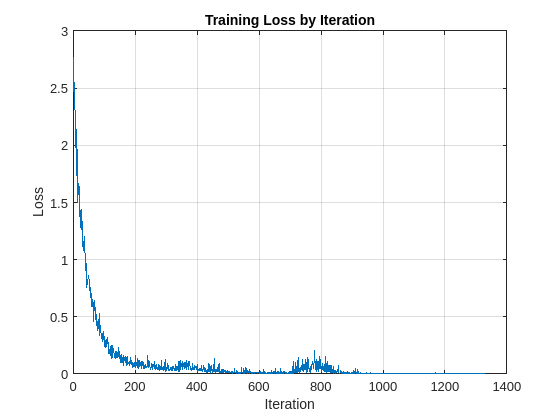

if progress == "final-loss"
        plot(1:iteration,lossByIteration)
        grid on 
        title('Training Loss by Iteration')
        xlabel("Iteration")
        ylabel("Loss")
end

miniBatchSize = 32;
mbqTest = minibatchqueue(transTest,2,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat', {'CBT','CB'}, ... 
    'MiniBatchFcn', @processSpeechMB);

numObservations = numel(adsTest.Files);
classes = string(unique(adsTest.Labels));

predictions = [];

% Loop over mini-batches
while hasdata(mbqTest)    
    % Read mini-batch of data
    dlX = next(mbqTest);

    % Make predictions on the minibatch
    dlYPred = predict(dlnet,dlX);

    % Determine corresponding classes
    predBatch = onehotdecode(dlYPred,classes,1);
    predictions = [predictions predBatch];  
end

accuracy = mean(predictions' == categorical(adsTest.Labels))

accuracy = 0.9883

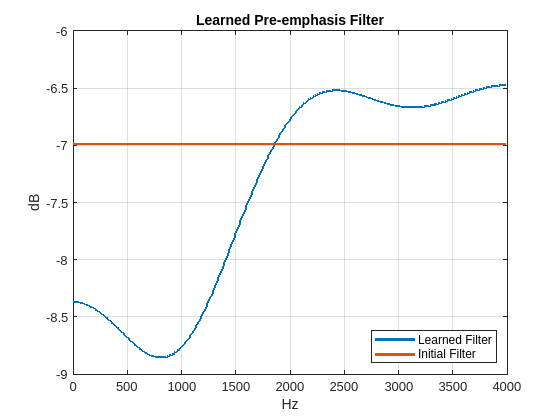

FIRFilter = dlnet.Layers(2).Weights;
[H,W] = freqz(FIRFilter,1,[],8000);
delta = kronDelta([5 1 1]);
Hinit = freqz(delta,1,[],4000);
plot(W,20*log10(abs([H Hinit])),'linewidth',2)
grid on
xlabel('Hz')
ylabel('dB')
legend('Learned Filter','Initial Filter','Location','SouthEast')
title('Learned Pre-emphasis Filter')

## Helper Functions:

function [out,info] = helperReadData(x,info)
% This function is only for use in the "Learn Pre-Emphasis Filter using
% Deep Learning" example. It may change or be removed in a
% future release.

N = numel(x);
x = single(x);
if N > 8192
    x = x(1:8192);
elseif N < 8192
    pad = 8192-N;
    prepad = floor(pad/2);
    postpad = ceil(pad/2);
    x = [zeros(prepad,1) ; x ; zeros(postpad,1)];
end
x = (x-mean(x))./std(x);
x = x(:)';
out = {x,info.Label};
end

function [dlX,dlY] = processSpeechMB(Xcell,Ycell)
% This function is only for use in the "Learn Pre-Emphasis Filter using
% Deep Learning" example. It may change or be removed in a
% future release.

Xcell = cellfun(@(x)reshape(x,1,1,[]),Xcell,'uni',false);
dlX = cat(2,Xcell{:});
dlY = cat(2,Ycell{:});
dlY = onehotencode(dlY,1);
end

function [grads,loss,state] = modelGradSTFT(net,X,T)
% This function is only for use in the "Learn Pre-Emphasis Filter using
% Deep Learning" example. It may change or be removed in a
% future release.

[y,state] = net.forward(X);
loss = crossentropy(y,T);
grads = dlgradient(loss,net.Learnables);
loss = double(gather(extractdata(loss)));
end